# **Authors**

*The work can be done in groups of up to 3 students. Please complete the following fields with your group number and list your names along with ISU ID numbers.*

**Stream: [RZZZ] Technical Vision**

**Subgroup: **

Student ID 1, Name 1

Student ID 2, Name 2

Student ID 3, Name 3

The task and guidelines were prepared by Andrei Zhdanov and Sergei Shavetov from ITMO University in 2024.

# **Practical Assignment No1. Histograms, Profiles, Projections**

Digital images basic brightness and geometric characteristics studying and using it for image analysis.

## **Introduction**

A digital image pixel is characterized by three parameters: $(x, y, I)$, where a pair of integer values $x, y$ describes the geometric position of the pixel in the image plane, and the $I$ value characterizes its brightness (intensity) at a point on the plane. Thus, the brightness and geometric components can be distinguished in the image.  In the general case, these components are not related to each other (for example, a change scene illumination will not change the geometric parameters of objects on the scene).  Because of this, it is easier to investigate the image brightness properties and the geometric ones separately. This approach reduces the studied image order in the case of geometric properties from $n = 3$ $(x, y, I)$ to $n = 2$ $(x, y)$, and in the brightness properties case to $n=1$ $(I)$. The image brightness component is characterized by a one-dimensional histogram array, from which the contrast can be calculated.

- **Histogram** is an occurrence frequency distribution of the same brightness pixels in the image.

- **Brightness** is an average signal intensity.

- **Contrast** is the values interval between the minimum and maximum image brightness.

To reduce the image geometric components to a one-dimensional data array $n = 1$ are used such characteristics as images "*profiles*" and "*projections*".

- **Profile** along the line is an intensity function of the image, distributed along this line.  

- **Projection** on the axis is a sum pixels intensities of the image, taken in the direction perpendicular to this axis.

## Task 1. Histograms

*Select an arbitrary low-contrast image. Perform histogram alignment and contrast stretching, use the considered transformations and built-in MATLAB functions. Compare the results.*

For an 8-bit grayscale image the histogram is a one-dimensional integer array $hist$ of 256 elements $[0 \dots 255]$. The histogram element $hist[i]$ is the image pixels sum with the brightness $i$. Using the visual form of the histogram we can assess the need to change the image brightness and contrast, estimate the area occupied by light and dark elements, determine the location on the image plane of individual objects corresponding to brightness certain ranges. For a RGB color image it is need to create three histograms for each color.

If the histogram is uneven for the image improving it can be equalized. Histogram equalization depending on the problem being solved can be performed in different ways.

At first, we will try calculating and displaying the histogram. To do it we have to:

    1. Read an image from file

    2. Process an image to calculate its histogram. If image consists of several color layers (e.g., *red*, *green* and *blue*) then we have to split it into layers first and then calculate histograms for each layer independently.

    3. Create new image canvas and draw a histogram on it.

    4. Display the histogram. Also, we may display an image aside.

So, let's do it.

### **1.1 Preparation**

First, we need to clear Command window and Workspace.

clc
clear all

### **1.2 Read image**

Now let's open our image which we will use during the current task. We will open it in RGB mode. We can convert RGB image to grayscale by calling ``rgb2gray(I)`` funtion.

For estimating grayscale image size we may use ``size(Igray)` `function, that returns three parameters: number of rows, number of columns and number of layers. 

% Read an image from file in RGB
I = imread('spb2.jpg');

% Convert RGB to grayscale
Igray = rgb2gray(I);

% Estimate image size
[numRows, numCols, Layers] = size(Igray);

### **1.3 Display image **

We can use ``imshow()`` function to display a single image. 

To display several images side-by-side we will use subplots function. At first, we need to start new figure with a keyword ``figure``. To set the grid for subplots with two rows and four columns we need to use ``subplot(2,3,1)`` function, where the third parameter is a place of the image in this grid. Using ``title('some title')`` function allows you to add title for this subplot.

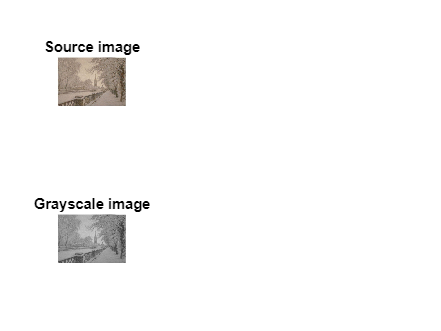

% Show image
% Starting the new figure
figure;

% Displaying image I in the first place of the grid
subplot(2,4,1);
imshow(I);
title('Source image');

% Displaying image Igray in the second place of the grid
subplot(2,4,5);
imshow(Igray);
title('Grayscale image');

### **1.4 Display image histogram**

Now we can display the images histograms in RGB and in Grayscale, using the function ``imhist()```.`

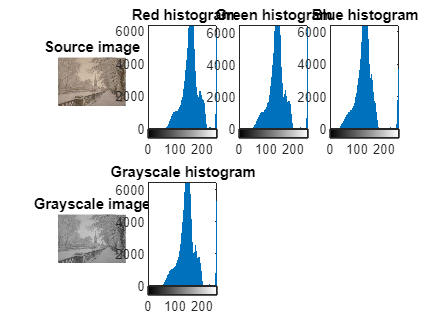

% Now let's show histograms
subplot(2,4,6);
imhist(Igray);
title('Grayscale histogram');

subplot(2,4,2);
imhist(I(:, :, 1));
title('Red histogram');

subplot(2,4,3);
imhist(I(:, :, 2));
title('Green histogram');

subplot(2,4,4);
imhist(I(:, :, 3));
title('Blue histogram');

From now on we will work with grayscale images as our task is to work with image intensities.

Now let's add the cummulative histogram calculation. To calculate it we will use ``cumsum()`` function.

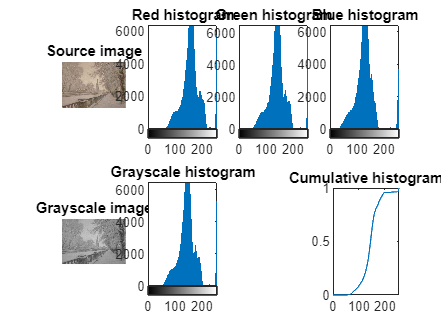

% Calculate cumulative histogram
cum_hist = cumsum(imhist(Igray)) ./ (numRows * numCols);

% Now let's show cumulative histogram
subplot(2,4,8);
plot(cum_hist);
title('Cumulative histogram');

# ***Self-work***

**Take some arbitrary image and display its histogram both in RGB and in grayscale color models.**

% TODO Place your solution here







### **1.5 Histogram transformations**

Now we are ready to try different histogram transformations.

#### **1.5.1 Arithmetic operations**

The simplest ways for histogram equalization are $\textit{arithmetic operations}$ on images. For example, if most of the histogram values are on the left, then the image is dark. To increase the detail in dark areas, it is need to shift the histogram to the right lighter area, for example, by `50` gradations for each color.

So, let's try shifting histogram by `50` to the right. Just add `50` to the image pixel by pixel:


$$I_{shift} = I + 50$$


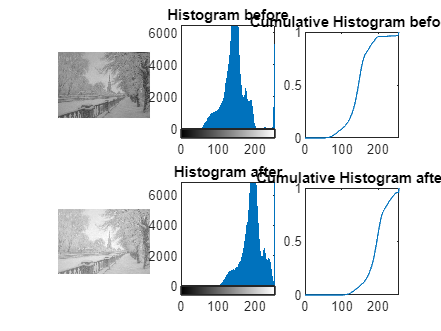

% Add 50 to each pixel
Ishift = Igray + 50;

% Let's also show histograms before and after to compare
figure;

subplot(2,3,1);
imshow(Igray);

subplot(2,3,4);
imshow(Ishift);

subplot(2,3,2);
imhist(Igray);
title('Histogram before');

subplot(2,3,5);
imhist(Ishift);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(Igray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Ishift)) ./ (numRows * numCols));
title('Cumulative Histogram after');

#### **1.5.2 Nonlinear dynamic range stretching**

In this case we will stretch the narrow range to a whole range using formula


$$I_{new[0,1]}(I) = \left( \frac{I - I_{min}}{I_{max} - I_{min}} \right) ^ \alpha$$


where $\alpha$ is a parameter of the nonlinear dynamic range stretching function, while $I_{min}$ and $I_{max}$ are minimum and maxiumum image intensity values correspondingly. This formula works in` [0, 1] `range.

*Please note that the fraction under power operation can become negative, so this should be correctly handled.*

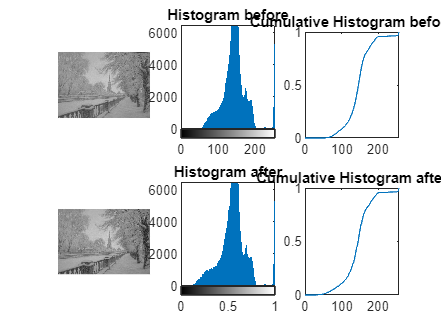

% Define coefficient
alfa = 0.8;

% Calculate minimum and maximum image intensity values
Imin = min(min(Igray));
Imax = max(max(Igray));

% Apply formula
Inew = ((double( Igray - Imin ) ./ double( Imax - Imin ))) .^ alfa;

% Let's also show histograms before and after to compare
figure;

subplot(2,3,1);
imshow(Igray);

subplot(2,3,4);
imshow(Inew);

subplot(2,3,2);
imhist(Igray);
title('Histogram before');

subplot(2,3,5);
imhist(Inew);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(Igray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Inew)) ./ (numRows * numCols));
title('Cumulative Histogram after');

#### **1.5.3 Uniform transformation**

The uniform transformation is carried out according to the formula


$$I_{new}(I) = (I_{max} - I_{min}) \cdot P(I) + I_{min}$$


where $P(I)$ is the image cummulative histogram, while $I_{min}$ and $I_{max}$ are minimum and maxiumum image intensity values correspondingly. Note that cummulative histogram is a floating point value function (array), so calculations should be done with floating point.

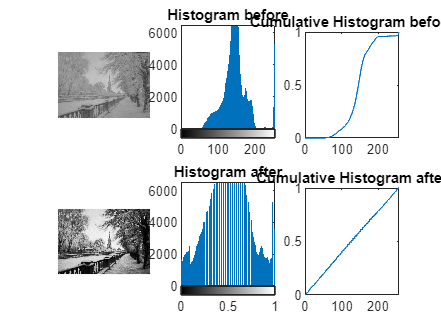

Imin = double(Imin / 255);
Imax = double(Imax / 255);
for i = 1:1: numRows;
    for j = 1:1: numCols;
        index = Igray(i,j);
        if index == 0;
            index = 1;
        end
        Inew(i,j) = (Imax - Imin) * cum_hist(index) + Imin;
    end
end

% Let's also show histograms before and after to compare
figure;

subplot(2,3,1);
imshow(Igray);

subplot(2,3,4);
imshow(Inew);

subplot(2,3,2);
imhist(Igray);
title('Histogram before');

subplot(2,3,5);
imhist(Inew);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(Igray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Inew)) ./ (numRows * numCols));
title('Cumulative Histogram after');

#### **1.5.4 Exponential transformation**

The exponential transformation is carried out according to the formula


$$I_{new[0,1]}(I) = I_{min} - \frac{1}{\alpha} \cdot \ln\left(1-P(I)\right)$$


where $I_{min}$ is a minimum image intensity value and $P(I)$ is image cummulative histogram. This formula works in `[0, 1] `floating point values range.

# ***Self-work***

**Finish the implementation of the exponential transformation.**

% TODO Place your solution here







#### **1.5.5 Rayleigh transformation**

The Rayleigh transformation is carried out according to the formula


$$I_{new[0,1]}(I) = I_{min}+\sqrt{2\alpha^2 \ln\left(\frac1{1-P(I)}\right)}$$


where $I_{min}$ is minimum image intensity value, $P(I)$ is image cummulative histogram, and $\alpha$ is constant characterizing the histogram of the resulting image elements intensity distribution.

This formula works in `[0, 1] `floating point values range.

*To avoid division by zero in formula implementation you may add epsilon.*

# ***Self-work***

**Finish the implementation of the Rayleigh transformation.**

% TODO Place your solution here







#### **1.5.6 2/3 degree transformation**

The 2/3 degree transformation is carried out according to the formula


$$I_{new[0,1]}(I) = P(I)^{2/3}$$


where $P(I)$ is image cummulative histogram.

This formula works in `[0, 1]` floating point values range.

# ***Self-work***

**Finish the implementation of the 2/3 degree transformation.**

% TODO Place your solution here







#### **1.5.7 Hyperbolic transformation**

The hyperbolic transformation is carried out according to the formula


$$I_{new[0,1]}(I) = \alpha^{P(I)}$$


where $P(I)$ is image cummulative histogram.

This formula works in `[0, 1]` floating point values range.

# ***Self-work***

**Finish the implementation of the hyperbolic transformation.**

% TODO Place your solution here







### **1.6 MATLAB built-in transformations**

In MATLAB are realized several functions for automatically equalizing grayscale image histograms:

- ``imadjust()`` adjust the image contrast by original image intensity range changing;

- ``histeq()`` enhance contrast using histogram equalization;

- ``adapthisteq()`` enhances the contrast of the grayscale image by transforming the values using contrast-limited adaptive histogram equalization (CLAHE).

#### `1.6.1 MATLAB built-in contrast adjust function`

It is executed by ``imadjust()`` function.

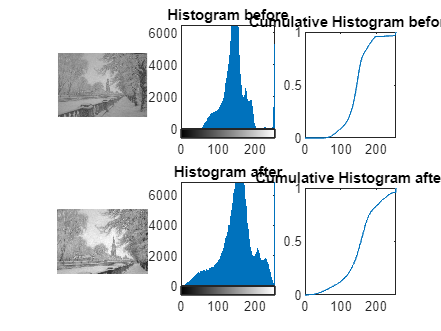

% Run imadjust() with these parameters
Inew = imadjust(Igray,[0.2 0.8]);

figure

subplot(2,3,1);
imshow(Igray);

subplot(2,3,4);
imshow(Inew);

subplot(2,3,2);
imhist(Igray);
title('Histogram before');

subplot(2,3,5);
imhist(Inew);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(Igray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Inew)) ./ (numRows * numCols));
title('Cumulative Histogram after');

# ***Self-work***

**Try running the same code for a different image and your own parameters.**

% TODO Place your solution here


#### **1.6.2 MATLAB built-in histogram equalization**

It is executed by ``histeq()`` function.

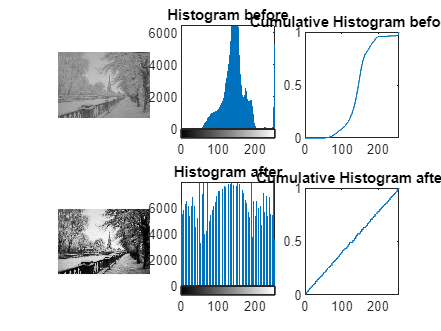

Inew = histeq(Igray);

figure

subplot(2,3,1);
imshow(Igray);

subplot(2,3,4);
imshow(Inew);

subplot(2,3,2);
imhist(Igray);
title('Histogram before');

subplot(2,3,5);
imhist(Inew);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(Igray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Inew)) ./ (numRows * numCols));
title('Cumulative Histogram after');

# ***Self-work***

**Try running the same code for a different image.**

% TODO Place your solution here


#### **1.6.3 MATLAB built-in adaptive histogram equalization**

It is executed by ``adapthisteq()`` function.

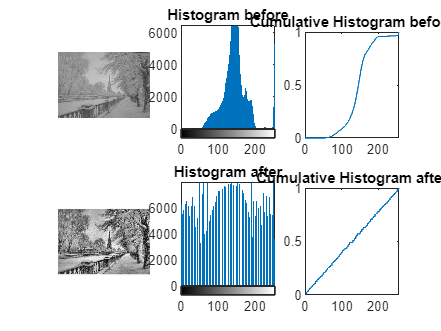

Inew = adapthisteq(Igray);

subplot(2,3,1);
imshow(Igray);

subplot(2,3,4);
imshow(Inew);

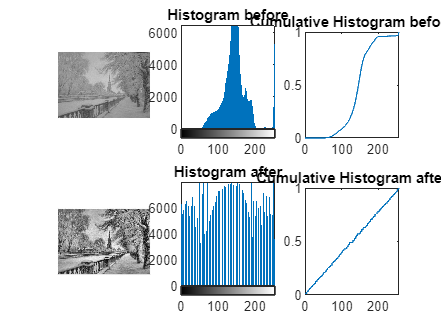

subplot(2,3,2);
imhist(Igray);
title('Histogram before');

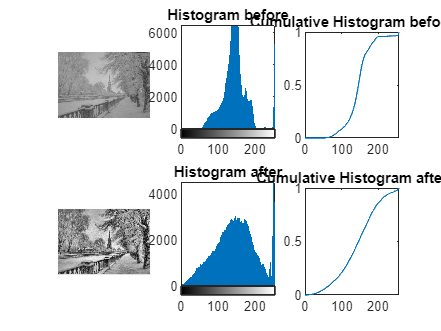


subplot(2,3,5);
imhist(Inew);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(Igray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Inew)) ./ (numRows * numCols));
title('Cumulative Histogram after');

# ***Self-work***

**Try running the same code for a different image.**

% TODO Place your solution here


## **Task 2. Profiles**

Select an arbitrary image containing a barcode. Calculate an image profile along the barcode.

**Image profile** along an arbitrary line is the intensity function image which is distributed along this line. The simplest case of image profile is a row profile:


$$profile(I, i, x)=I(x,i)$$


where $i$ is the row number of the image $I$.

Column profile is:


$$profile(I, j, y)=I(j,y)$$


where $j$ is the column number of the image $I$.

In general case, an image profile can be considered along arbitrary straight, poly or curved line intersects the image. After image profile array getting it can be analyzed using standard approaches. The analysis allows to automatically highlight the special points of the profile function corresponding to the image contours intersected by this line. For example, if we calculate the profile of the barcode image along the axis intersecting barcode lines, we can then process it to extract the information about lines thickness and easily calculate the barcode code value.

Let's do the simple way by slicing the image as an array. If we need a profile along arbitrary line then we can first rotate an image and then do a profile along new horizontal or vertical axis. We will learn how to rotate image later in this course.

First, let's open an image with barcode.

% Read image
I = imread('штрихкод.jpg');
Igray = rgb2gray(I);

Now let's do a slice right in the middle to get a barcode profile. Then we will display it.

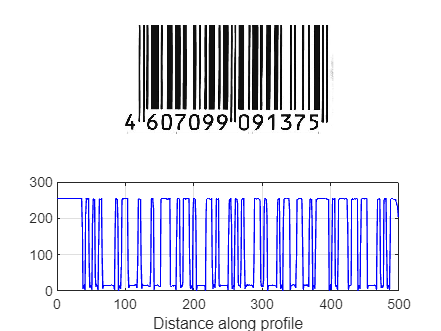

[numRows, numCols, Layers] = size(Igray);
x = [1 numCols];
y = [ceil(numRows / 2) ceil(numRows / 2)];
figure
subplot(2,1,1);
imshow(Igray);
subplot(2,1,2);
improfile(Igray(:,:,1),x,y), grid on;

# ***Self-work***

**Take some arbitrary barcode image and calculate the image profile.**

% TODO Place your solution here
  
  
  




## **Task 3. Projections**

Select an arbitrary image containing monotone areas and prominent objects. Calculate image projections on the vertical and horizontal axes. Define the objects boundaries.

To do this first we need to read and image.

% Read image
I = imread('Flag_of_Japan.jpg');

As we have black text on white background, let's binarize it using ``imbinarize()`` function and invert to filter some noise using **~** opertor.

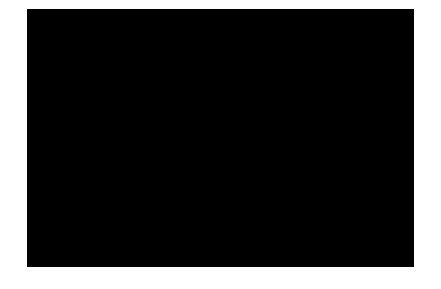

% Invert and convert to BW
Ibw = imbinarize(I);
Ibw = ~Ibw(:,:,1);
[numRows, numCols, Layers] = size(Ibw);

figure
imshow(Ibw);

Now we can calculate projections with ``sum()`` method. Projection to $X$ axis is done by summing with axis ``0`` and projection to $Y$ axis is done by summing with axis ``1```.`

% Do projection

for i=1:1:numRows
    ProjOy(i,1) = sum(Ibw(i, :));
end
for i=1:1:numCols
    ProjOx(1,i) = sum(Ibw(:, i));
end

And display them same as we did before for histograms.

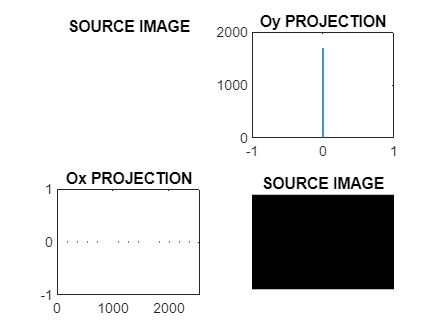

figure

subplot(2,2,1);
imshow(~Ibw);
title('SOURCE IMAGE');

subplot(2,2,2);
plot(ProjOy,1:numRows);
title('Oy PROJECTION');

subplot(2,2,3);
plot(1:numCols,ProjOx);
title('Ox PROJECTION');

subplot(2,2,4);
imshow(Ibw);
title('SOURCE IMAGE');

Next we need to find first and last non-zero elements in the projections.

% Find non-zero element indices
k = find(ProjOx);
kmin = k(1);

Index exceeds the number of array elements. Index must not exceed 0.

kmax = k(length(k));

y = find(ProjOy);
ymin = y(1);
ymax = y(length(y));

fprintf("The object position is from %d to %d along X axis and from %d to %d along Y axis", kmin, kmax, ymin, ymax);

Now when we know the range, we can highlight it on our source image with ``line()`` function.

figure
imshow(Ibw);
x = [kmin kmax kmax kmin kmin];
y = [ymin ymin ymax ymax ymin];
line(x,y,'Color','red','LineStyle','-', 'LineWidth',3)

# ***Self-work***

**Take some arbitrary image containing contrast areas and calculate the object position.**

% TODO Place your solution here




  
  

# ***Self-work***

**Optional: 1 extra point**

**Can you use projections to find several object positions on the single image? In which cases will this method work?**

% TODO Place your solution here





  
  

## **Questions**

Please answer the following questions:

 - What is the image contrast and how can you change it?

** > Put your answer here**

 - Why is effective using of image profiles and projections?

** > Put your answer here**

 - How can you find an object against a uniform background?

** > Put your answer here**

## **Conclusion**

What have you learned with this task? Don't forget to conclude it.

 **> Put your answer here**